close all;clear all; clc;

Lya_index = 2;
sys = p4_system_formulate; 
sys.f = p4_gp(sys);

Error using rng
The current random number generator is the legacy generator.  This is because you have executed a command such as rand('state',0), which activates MATLAB's legacy
random number behavior.  You may not use RNG to reseed the legacy random number generator.

Use rng('default') to reinitialize the random number generator to its startup configuration, or call RNG using a specific generator type, such as
rng(seed,'twister').

Error in p4_gpr_xdot2 (line 12)
rng(1)

Error in 

sys.plott = 1; % Plot figure

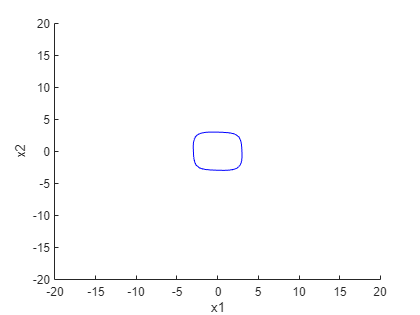

sys = p4_s1_lya_sublevelset(sys,Lya_index);

Elapsed time is 43.209959 seconds.


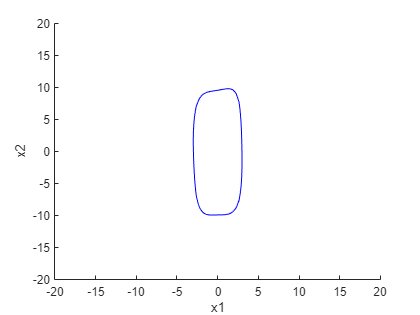

[opt_input, sys] = p4_s2_opt_barrier(sys);

bar_flag = sys.exist_bar

bar_flag =      1


x = linspace(-5,5,10);
y = linspace(-15,15,10);
[X, Y] = meshgrid(x,y);
syms x1 x2
KK = p2s(opt_input(3));
ZZ = zeros(10,10);

for i = 1:length(x)
    for j = 1:length(y)
    ZZ(i,j) = double(subs(KK,{x1,x2},{x(i),y(j)}));
    end
end

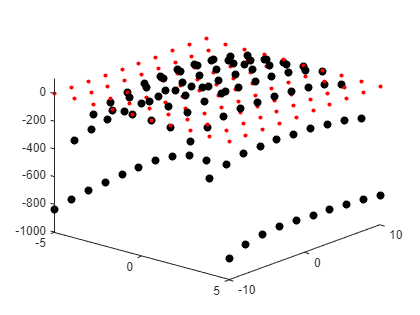

figure(44);clf; hold on;
for i = 1:length(x)
    for j = 1:length(y)
        plot3(x(i),y(j),ZZ(i,j),'k.','MarkerSize',20);
        plot3(x(i),y(j),0,'r.','MarkerSize',10);
    end
end

view([49 20])

% contour(X,Y,ZZ)

%% Check permissive Lyapunov function
if isequal(bar_flag,1)
    %         sys.exist_bar = 1;
    [coe, fac] = coeffs(p2s(opt_input));
    coe = double(coe);
    fac = char(fac);
    save('.\mat\gp_coe.mat','coe')
else
    %         sys.exist_bar = 0;
    opt_input = sys.cv-sys.V(Lya_index);
    [coe, fac] = coeffs(p2s(opt_input));
    coe = double(coe);
    fac = char(fac);
    save('.\mat\gp_coe.mat','coe')
end